% script RR_passive_filters
% Solves the basic equations of four simple passive filters.
% These are all quite easily solved by hand, but these examples well illustrate how
% to put a handful of linear equations into A*x=b form and solve using Matlab.
% This general strategy is quite useful, because it easily extends to much larger systems
% of linear equations, which are tedios (and, quite prone to error) if solving by hand.
% Renaissance Robotics codebase, Chapter 10, https://github.com/tbewley/RR
% Copyright 2023 by Thomas Bewley, distributed under Modified BSD License.

clear, clf, close all, syms s V_i V_s C C_d L R R1 R2

% First-order low-pass RC filter: Solve for V_o as a function of V_i
% x={I_C,I_R,V_o}  <-- unknown vector   
A  =[ 1  -1   0;     % I_C - I_R = 0
      1   0 -C*s;    % I_C - C*s*V_o = 0
      0   R   1];    % R*I_R + V_o = V_i
b  =[ 0; 0; V_i];
x=A\b; LPF1=simplify(x(3))

$$LPF1 = \frac{V_{i}}{C\,R\,s+1}$$

omega1=10; F_LPF1=RR_tf(omega1,[1 omega1]); figure(1), RR_bode(F_LPF1)


% First-order high-pass RC filter: Solve for V_o as a function of V_i
% x={I_C,I_R,V_o}  <-- unknown vector  
A  =[ 1  -1   0;     % I_C - I_R = 0
      1   0  C*s;    % I_C + C*s*V_o = C*s*V_i
      0   R  -1];    % R*I_R - V_o = 0
b  =[ 0; C*s*V_i; 0];
x=A\b; HPF1=simplify(x(3))

$$HPF1 = \frac{C\,R\,V_{i}\,s}{C\,R\,s+1}$$

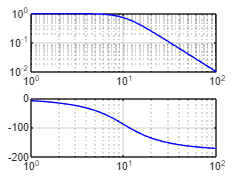

omega1=10; F_HPF1=RR_tf([1 0],[1 omega1]); figure(2), RR_bode(F_HPF1)


% Voltage-biased first-order high-pass RC filter: Solve for V_o as a function of V_i and V_s
% x={I_0,I_1,I_2,V_o}  <-- unknown vector
A  =[ 1   1  -1   0;   % I_C + I_1 - I_2 = 0
      1   0   0  C*s;  % I_C + C*s*V_o = C*s*V_i
      0  R1   0   1;   % R1*I_1 + V_o = V_s
      0   0  R2  -1];  % R2*I_2 - V_o = 0
b  =[ 0; C*s*V_i; V_s; 0];
x=A\b; HPF1biased=simplify(x(4))

$$HPF1biased = \frac{R_{2}\,\left(V_{s}+C\,R_{1}\,V_{i}\,s\right)}{R_{1}+R_{2}+C\,R_{1}\,R_{2}\,s}$$


%%%Q1 and Q2
% Second-order low-pass LC filter: Solve for V_o as a function of V_i
% x={I_L,I_C,I_R, V_o}  <-- unknown vector
A  =[1  -1  -1  0 ;
     L*s  0  0  1 ;   
     0  -1  0  C*s;
     0  0  1  -1];
b  =[0  ;  V_i  ;  0  ;  0];
x=A\b; LPF2=simplify(x(3))

$$LPF2 = \frac{V_{i}}{C\,L\,s^{2}+L\,s+1}$$

omega4=10; zeta=1; F_LPF2=RR_tf([omega4^2],[1 2*zeta*omega4 omega4^2]); figure(3), RR_bode(F_LPF2)

%%%Q3 and Q4
% Second-order low-pass LC filter: Solve for V_o as a function of V_i
% x={I_L,I_C,I_R, V_o}  <-- unknown vector
A  =[1  -1  -1  0 ;
     L*s  0  0  1 ;   
     0  1/(C*s)  0  0;
     0  0  (1/(C_d*s)+R)  0];
b  =[0  ;  V_i  ;  V_i  ;  V_i];
x=A\b; LPF2=simplify(x(3))

$$LPF2 = \frac{C_{d}\,V_{i}\,s}{C_{d}\,R\,s+1}$$

omega4=10; zeta=1; F_LPF2=RR_tf([omega4^2],[1 2*zeta*omega4 omega4^2]); figure(3), RR_bode(F_LPF2)